clc;
clear;
% Define the range of the variable
theta = [-1:0.01:3].'

theta =    -1.0000
   -0.9900
   -0.9800
   -0.9700
   -0.9600
   -0.9500
   -0.9400
   -0.9300
   -0.9200
   -0.9100


alpha = 2;
% Initialize the matrix A
A = [theta- 2, theta, theta - alpha].'

A =    -3.0000   -2.9900   -2.9800   -2.9700   -2.9600   -2.9500   -2.9400   -2.9300   -2.9200   -2.9100   -2.9000   -2.8900   -2.8800   -2.8700   -2.8600   -2.8500   -2.8400   -2.8300   -2.8200   -2.8100   -2.8000   -2.7900   -2.7800   -2.7700   -2.7600   -2.7500   -2.7400   -2.7300   -2.7200   -2.7100   -2.7000   -2.6900   -2.6800   -2.6700   -2.6600   -2.6500   -2.6400   -2.6300   -2.6200   -2.6100   -2.6000   -2.5900   -2.5800   -2.5700   -2.5600   -2.5500   -2.5400   -2.5300   -2.5200   -2.5100
   -1.0000   -0.9900   -0.9800   -0.9700   -0.9600   -0.9500   -0.9400   -0.9300   -0.9200   -0.9100   -0.9000   -0.8900   -0.8800   -0.8700   -0.8600   -0.8500   -0.8400   -0.8300   -0.8200   -0.8100   -0.8000   -0.7900   -0.7800   -0.7700   -0.7600   -0.7500   -0.7400   -0.7300   -0.7200   -0.7100   -0.7000   -0.6900   -0.6800   -0.6700   -0.6600   -0.6500   -0.6400   -0.6300   -0.6200   -0.6100   -0.6000   -0.5900   -0.5800   -0.5700   -0.5600   -0.5500   -0.5400   -0.5300   -0.5200   -0

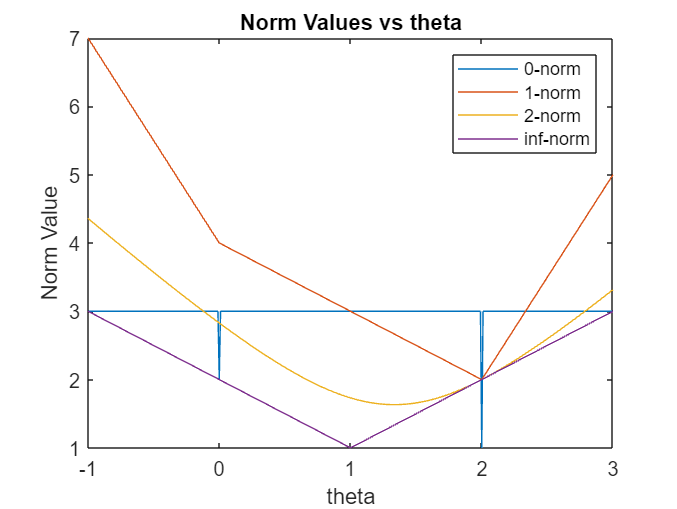

% Define the values of p
p_values = [0, 1, 2, Inf];
% Initialize the norm values
norm_values = zeros(length(p_values), length(theta));
% Calculate the norms
for i = 1:length(p_values)
 if p_values(i) == 0
 norm_values(i, :) = sum(A ~= 0); % zero_norm = no.of non-zero elements
 elseif isinf(p_values(i))
 norm_values(i, :) = max(abs(A)); % inf_norm = element with max absolute value
 else
 norm_values(i, :) = sum(abs(A).^p_values(i)).^(1/p_values(i));
 end
end


figure;
plot(theta,norm_values(1,:),theta,norm_values(2,:),theta,norm_values(3,:),theta,norm_values(4,:))
title('Norm Values vs theta');
ylabel('Norm Value');
xlabel('theta');
legend('0-norm', '1-norm', '2-norm', 'inf-norm')

clc;
clear;
% Define the range of the variable
theta = [-1:0.01:3].'

theta =    -1.0000
   -0.9900
   -0.9800
   -0.9700
   -0.9600
   -0.9500
   -0.9400
   -0.9300
   -0.9200
   -0.9100


alpha = -1;
% Initialize the matrix A
A = [theta- 2, theta, theta - alpha].'

A =    -3.0000   -2.9900   -2.9800   -2.9700   -2.9600   -2.9500   -2.9400   -2.9300   -2.9200   -2.9100   -2.9000   -2.8900   -2.8800   -2.8700   -2.8600   -2.8500   -2.8400   -2.8300   -2.8200   -2.8100   -2.8000   -2.7900   -2.7800   -2.7700   -2.7600   -2.7500   -2.7400   -2.7300   -2.7200   -2.7100   -2.7000   -2.6900   -2.6800   -2.6700   -2.6600   -2.6500   -2.6400   -2.6300   -2.6200   -2.6100   -2.6000   -2.5900   -2.5800   -2.5700   -2.5600   -2.5500   -2.5400   -2.5300   -2.5200   -2.5100
   -1.0000   -0.9900   -0.9800   -0.9700   -0.9600   -0.9500   -0.9400   -0.9300   -0.9200   -0.9100   -0.9000   -0.8900   -0.8800   -0.8700   -0.8600   -0.8500   -0.8400   -0.8300   -0.8200   -0.8100   -0.8000   -0.7900   -0.7800   -0.7700   -0.7600   -0.7500   -0.7400   -0.7300   -0.7200   -0.7100   -0.7000   -0.6900   -0.6800   -0.6700   -0.6600   -0.6500   -0.6400   -0.6300   -0.6200   -0.6100   -0.6000   -0.5900   -0.5800   -0.5700   -0.5600   -0.5500   -0.5400   -0.5300   -0.5200   -0

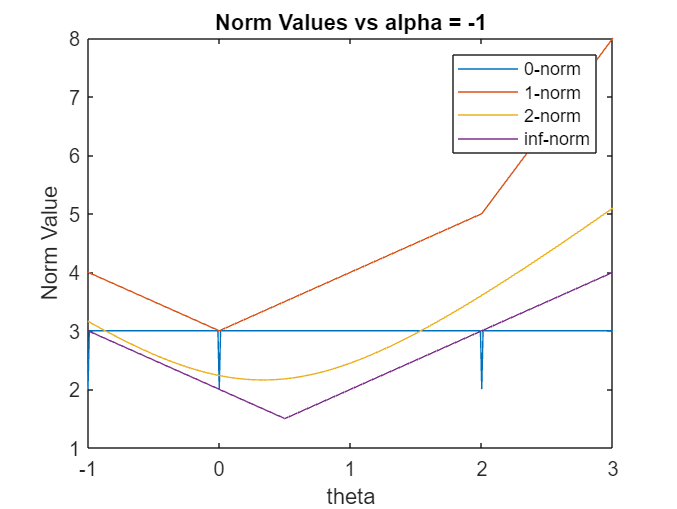

% Define the values of p
p_values = [0, 1, 2, Inf];
% Initialize the norm values
norm_values = zeros(length(p_values), length(theta));
% Calculate the norms
for i = 1:length(p_values)
 if p_values(i) == 0
 norm_values(i, :) = sum(A ~= 0); % zero_norm = no.of non-zero elements
 elseif isinf(p_values(i))
 norm_values(i, :) = max(abs(A)); % inf_norm = element with max absolute value
 else
 norm_values(i, :) = sum(abs(A).^p_values(i)).^(1/p_values(i));
 end
end


figure;
plot(theta,norm_values(1,:),theta,norm_values(2,:),theta,norm_values(3,:),theta,norm_values(4,:))
title('Norm Values vs alpha = -1');
ylabel('Norm Value');
xlabel('theta');
legend('0-norm', '1-norm', '2-norm', 'inf-norm')

clc;
clear;
v1 = [0.9,-0.4].'

v1 =     0.9000
   -0.4000


x1 = linspace(1,10,100)

x1 =     1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545


x2 = linspace(90,190,100)

x2 =    90.0000   91.0101   92.0202   93.0303   94.0404   95.0505   96.0606   97.0707   98.0808   99.0909  100.1010  101.1111  102.1212  103.1313  104.1414  105.1515  106.1616  107.1717  108.1818  109.1919  110.2020  111.2121  112.2222  113.2323  114.2424  115.2525  116.2626  117.2727  118.2828  119.2929  120.3030  121.3131  122.3232  123.3333  124.3434  125.3535  126.3636  127.3737  128.3838  129.3939  130.4040  131.4141  132.4242  133.4343  134.4444  135.4545  136.4646  137.4747  138.4848  139.4949


x = [x1; x2].'

x =     1.0000   90.0000
    1.0909   91.0101
    1.1818   92.0202
    1.2727   93.0303
    1.3636   94.0404
    1.4545   95.0505
    1.5455   96.0606
    1.6364   97.0707
    1.7273   98.0808
    1.8182   99.0909


x*v1

ans =   -35.1000
  -35.4222
  -35.7444
  -36.0667
  -36.3889
  -36.7111
  -37.0333
  -37.3556
  -37.6778
  -38.0000


clc;
clear;
